# Histogram of Vector

Generate 10,000 random numbers and create a histogram. The `histogram` function automatically chooses an appropriate number of bins to cover the range of values in `x` and show the shape of the underlying distribution.

`X = randn(`[`n`](https://www.mathworks.com/help/releases/R2023b/matlab/ref/randn.html?overload=randn%20false&doclanguage=zh-CN&nocookie=true&prodfilter=ML%20DH%20NN&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DKOJ6NL%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=KWZABK&container=jshelpbrowser#bufqhx9-n)`)` 返回由正态分布的随机数组成的 `n`×`n` 矩阵。

`X = randn(`[`sz1,...,szN`](https://www.mathworks.com/help/releases/R2023b/matlab/ref/randn.html?overload=randn%20false&doclanguage=zh-CN&nocookie=true&prodfilter=ML%20DH%20NN&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DKOJ6NL%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=KWZABK&container=jshelpbrowser#bufqhx9-sz1szN)`)` 返回由随机数组成的 `sz1`×...×`szN` 数组，其中 `sz1,...,szN` 指示每个维度的大小。例如：`randn(3,4)` 返回一个 3×4 的矩阵。

从标准复数正态分布生成 10 个随机复数。

a = randn(10,1,"like",1i)

a =    0.9106 - 0.5033i
  -0.1172 + 0.4941i
   0.6795 - 0.3375i
   1.3279 - 1.0679i
   0.5420 - 0.1424i
   0.1660 + 0.3122i
  -0.3438 + 0.0762i
   0.1658 + 0.1503i
   0.1108 + 0.0266i
   0.3563 + 0.1597i


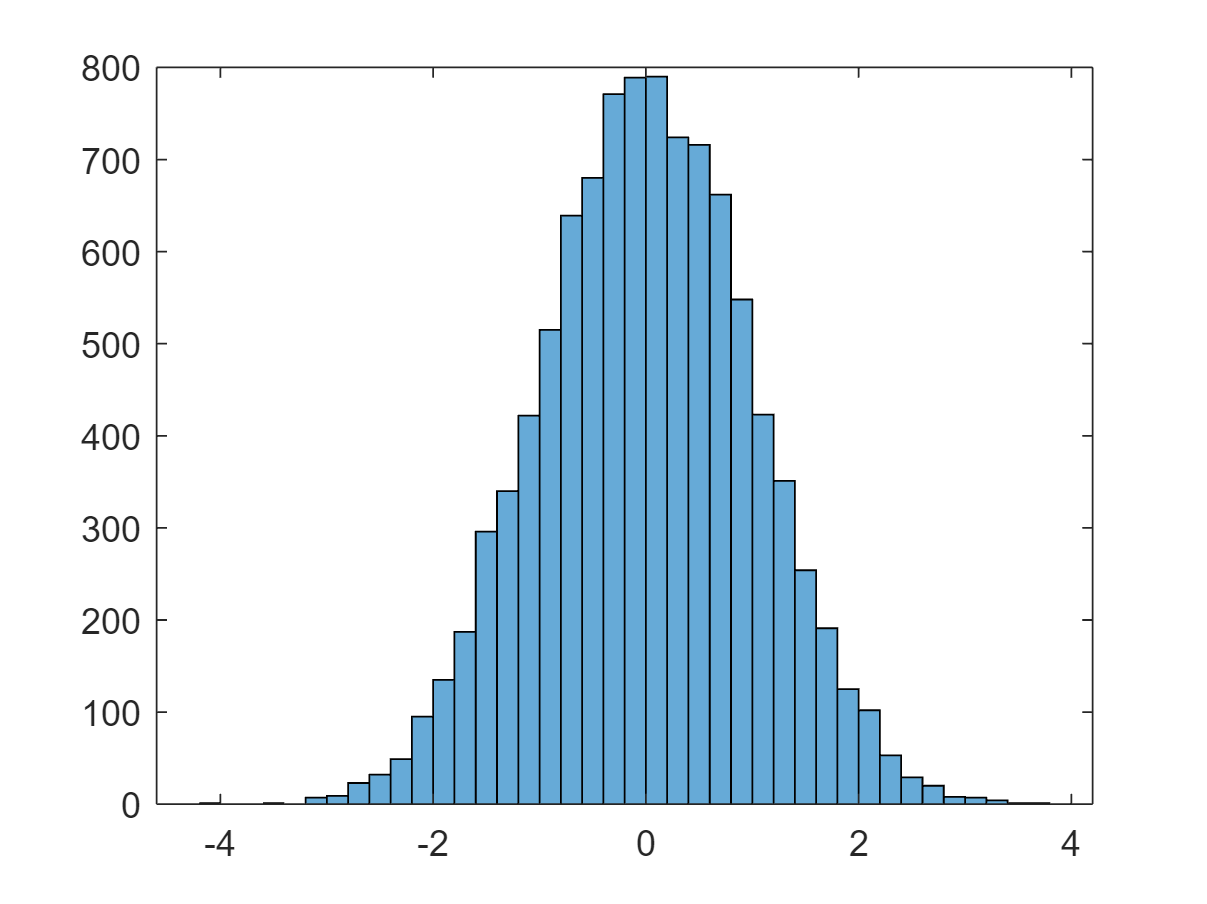

x = randn(10000,1);
h = histogram(x);

When you specify an output argument to the `histogram` function, it returns a histogram object. You can use this object to inspect the properties of the histogram, such as the number of bins or the width of the bins.

## Customization

Display Normalized Data on Y-Axis

Instead of using the count on the y-axis, you can also view the proportion of each bin of the overall set on the y-axis using the *Normalization* property as a Name, Value pair argument to `histogram`.

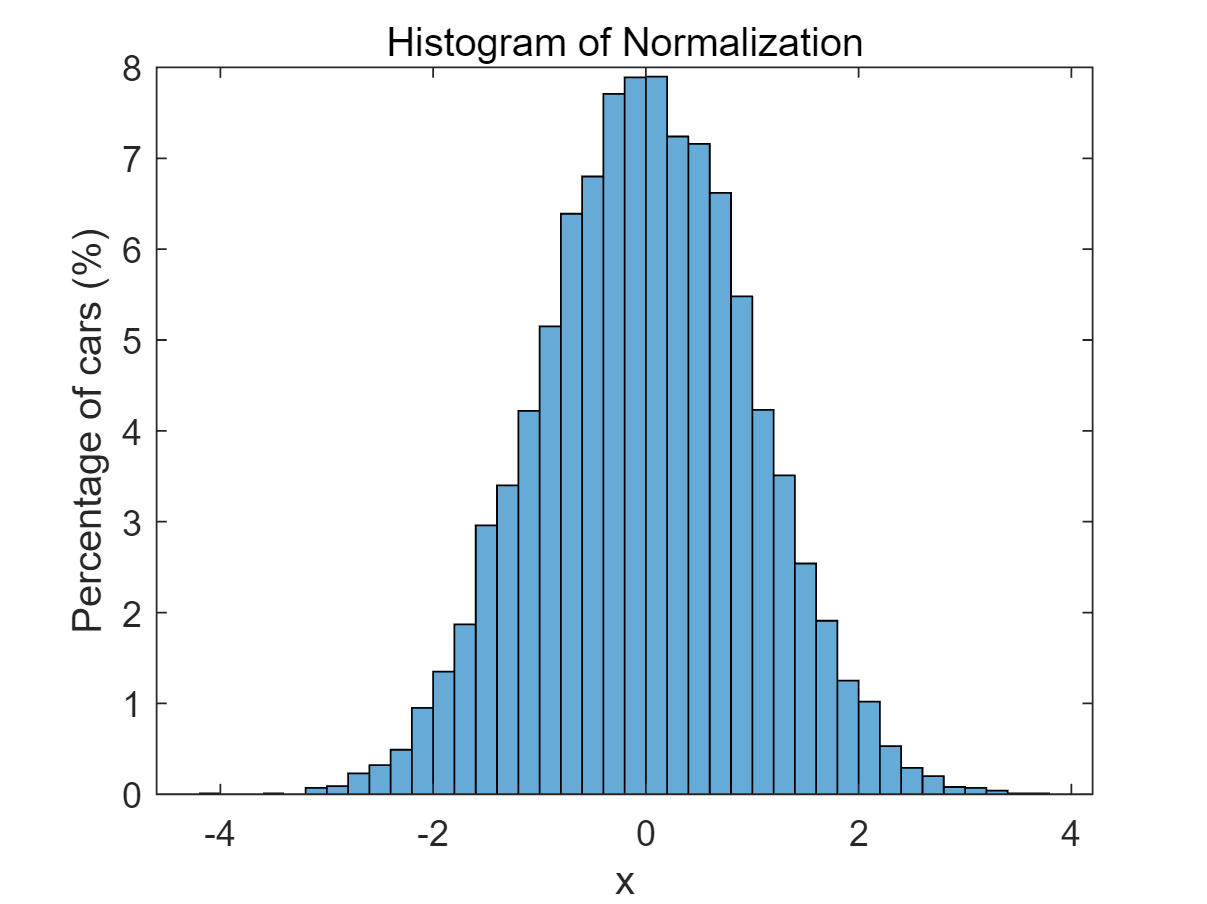

h = histogram(x,...    
    "Normalization","probability");      % Specify "probability" in the Normalization field 
title("Histogram of Normalization")
xlabel("x")
ylabel("Percentage of cars (%)")
yticklabels(yticks*100);                % Set the y-axis label values to represent percentages

# **加载相机和预训练网络**

连接到相机并加载预训练的 GoogLeNet 网络。您可以在此步骤使用任何预训练网络。该示例需要 MATLAB Support Package for USB Webcams，以及 Deep Learning Toolbox™ Model *for GoogLeNet Network*。如果没有安装所需的支持包，软件会提供下载链接。

camera = webcam;
net = googlenet;

如果要再次运行该示例，请先运行命令 `clear camera`，其中 `camera` 是与网络摄像头的连接。否则将出现错误，因为您不能创建与同一网络摄像头的另一连接。

# **对相机快照进行分类**

要对图像进行分类，必须将其大小调整为网络的输入大小。获取网络的图像输入层的 `InputSize` 属性的前两个元素。图像输入层是网络的第一层。

inputSize = net.Layers(1).InputSize(1:2)

显示来自相机的图像以及预测的标签及其概率。在调用 `classify` 之前，必须将图像大小调整为网络的输入大小。

[`Y`](https://www.mathworks.com/help/releases/R2023b/deeplearning/ref/seriesnetwork.classify.html?searchHighlight=classify&s_tid=doc_srchtitle#d126e34853) `=` `classify``(`[`net`](https://www.mathworks.com/help/releases/R2023b/deeplearning/ref/seriesnetwork.classify.html?searchHighlight=classify&s_tid=doc_srchtitle#d126e32995)`,`[`images`](https://www.mathworks.com/help/releases/R2023b/deeplearning/ref/seriesnetwork.classify.html?searchHighlight=classify&s_tid=doc_srchtitle#mw_bfe43a19-ce2d-4b8f-9e7a-3711c9408e0e_sep_mw_99c47767-d581-463d-a32e-fd1427314607)`)` predicts the class labels of the specified images using the trained network `net`.

figure('Name',"predict object");
im = snapshot(camera);
image(im)
im = imresize(im,inputSize);
[label,score] = classify(net,im);
title({char(label),num2str(max(score),2)});

# **连续对相机图像进行分类**

要连续对相机图像进行分类，请将前面的步骤放入一个循环。在图窗打开时运行该循环。要停止实时预测，只需关闭图窗。在每次迭代结束时使用 `drawnow` 更新图窗。

h = figure('Name',"predict object");
while ishandle(h)
    im = snapshot(camera);
    image(im)
    im = imresize(im,inputSize);
    [label,score] = classify(net,im);
    title({char(label), num2str(max(score),2)});
    drawnow
end

# **显示排名靠前的预测值**

预测出的类可能快速更改。因此，将排名靠前的预测值显示在一起会有所帮助。您可以通过绘制预测分数靠前的类来显示排名前五的预测值及其概率。

对相机的快照进行分类。显示来自相机的图像以及预测的标签及其概率。使用 `classify` 函数的 `score` 输出显示排名前五的预测值的概率直方图。

创建图窗窗口。首先，调整窗口大小以使宽度增加一倍，并创建两个子图。

h = figure;
h.Position(3) = 2*h.Position(3);
ax1 = subplot(1,2,1);
ax2 = subplot(1,2,2);

在左侧子图中，将图像和分类显示在一起。

im = snapshot(camera);
image(ax1,im)
im = imresize(im,inputSize);
[label,score] = classify(net,im);
title(ax1,{char(label),num2str(max(score),2)});

通过选择分数最高的类来选择排名前五的预测值。

[~,idx] = sort(score,'descend');
idx = idx(5:-1:1);
classes = net.Layers(end).Classes;
classNamesTop = string(classes(idx));
scoreTop = score(idx);

将排名前五的预测值显示为直方图。

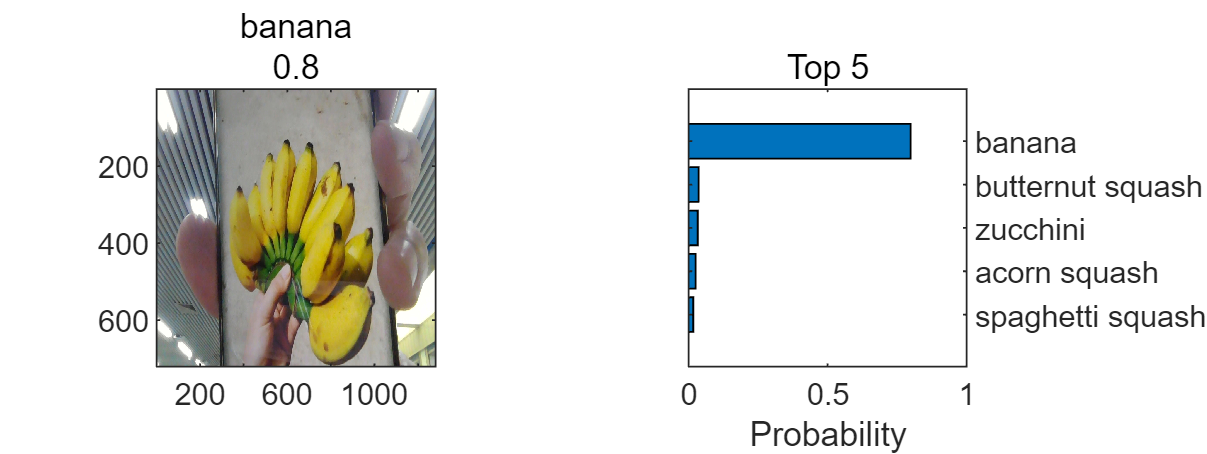

barh(ax2,scoreTop)
xlim(ax2,[0 1])
title(ax2,'Top 5')
xlabel(ax2,'Probability')
yticklabels(ax2,classNamesTop)
ax2.YAxisLocation = 'right';

# **连续分类图像并显示排名靠前的预测值**

要连续对来自相机的图像进行分类并显示排名靠前的预测值，请将前面的步骤放入一个循环。在图窗打开时运行该循环。要停止实时预测，只需关闭图窗。在每次迭代结束时使用 `drawnow` 更新图窗。

创建图窗窗口。首先调整窗口大小以使宽度增加一倍，并创建两个子图。要防止坐标区大小改变，请将 `PositionConstraint` 属性设置为 `'innerposition'`。

h = figure;
h.Position(3) = 2*h.Position(3);
ax1 = subplot(1,2,1);
ax2 = subplot(1,2,2);
ax2.PositionConstraint = 'innerposition';

连续显示并分类图像，同时显示排名前五的预测值的直方图。

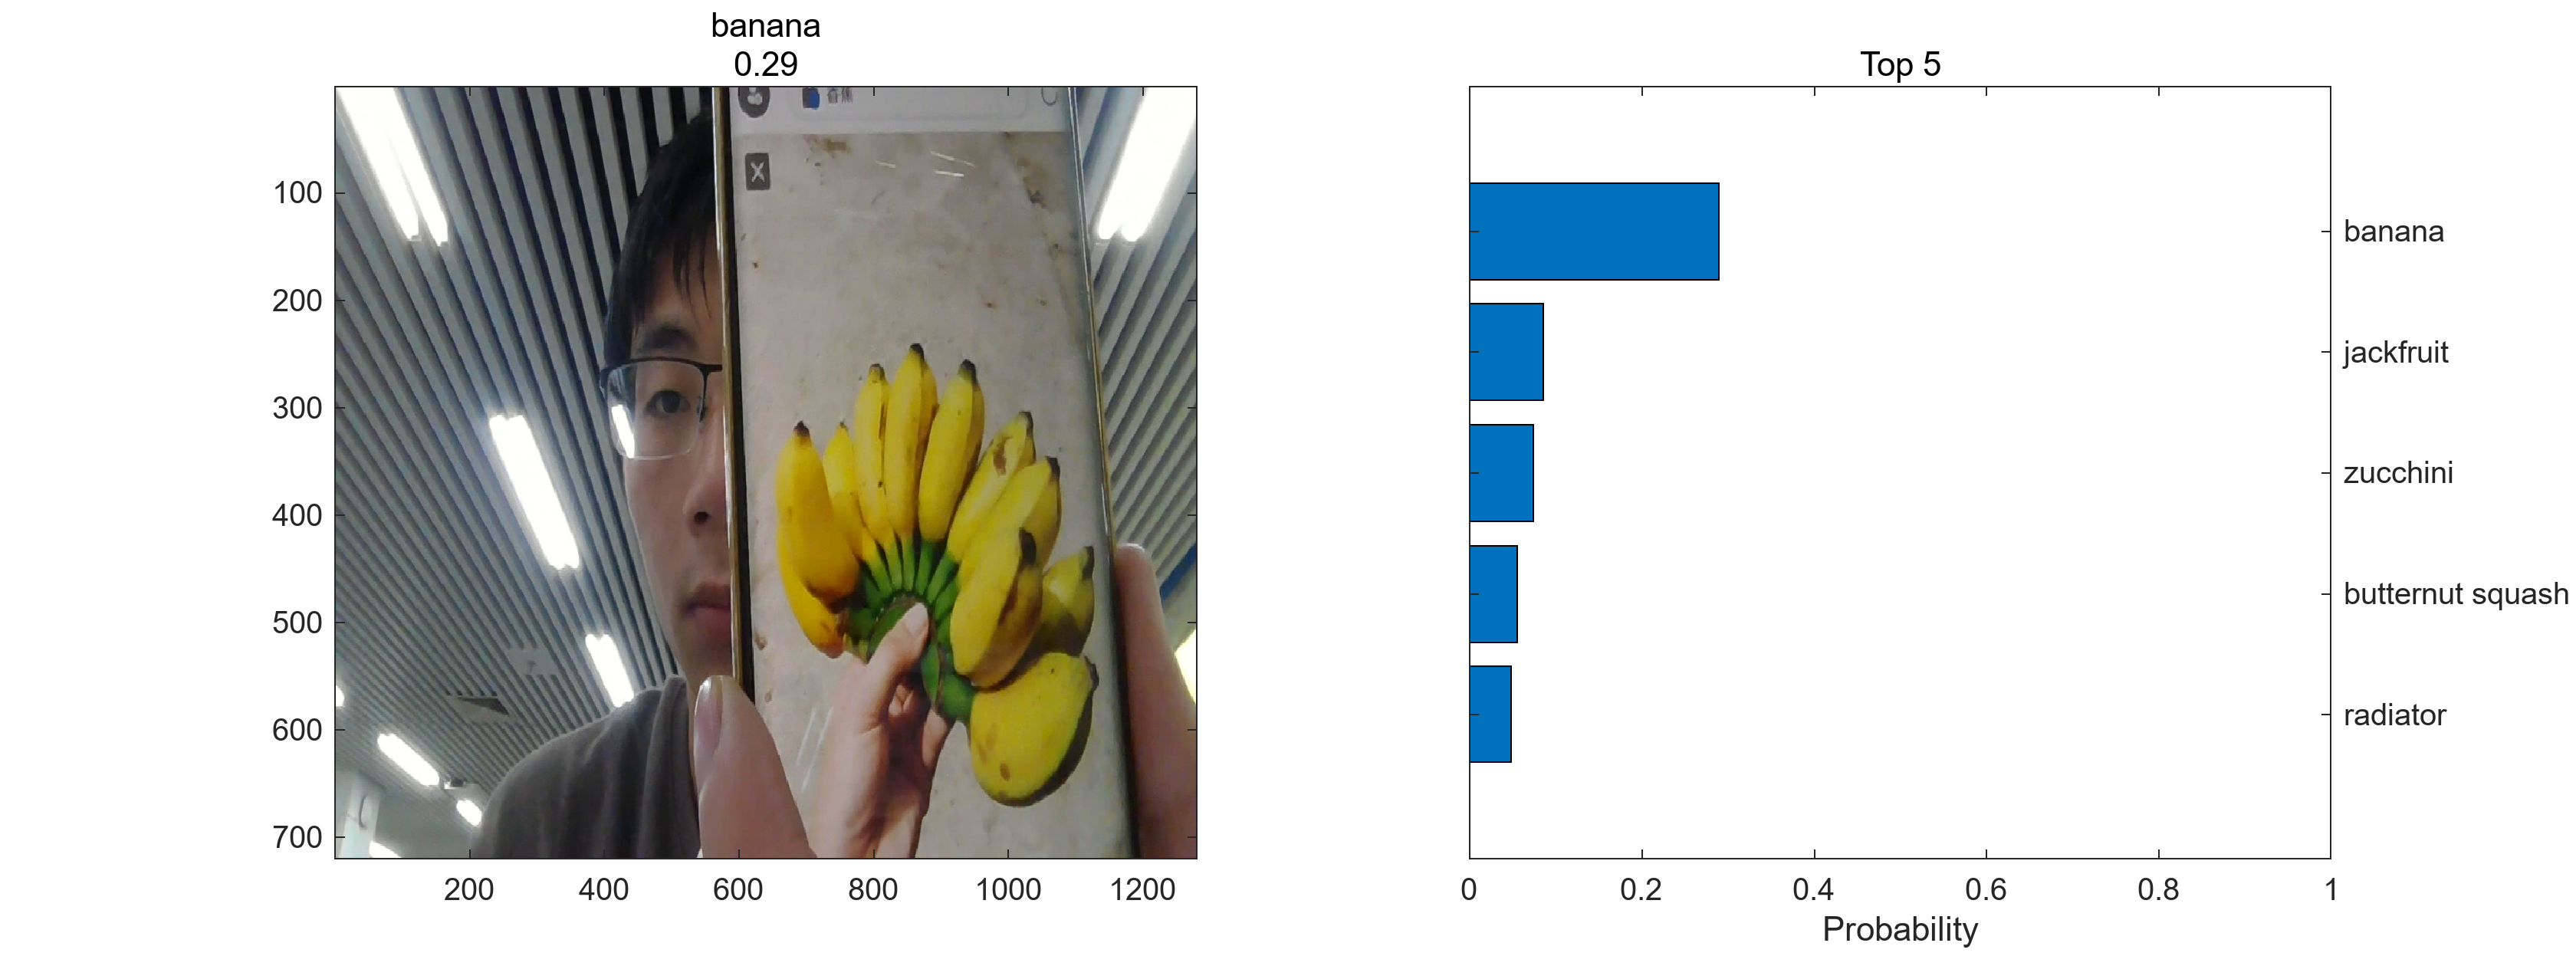

while ishandle(h)
    % Display and classify the image
    im = snapshot(camera);
    image(ax1,im)
    im = imresize(im,inputSize);
    [label,score] = classify(net,im);
    title(ax1,{char(label),num2str(max(score),2)});
    
    % Select the top five predictions
    [~,idx] = sort(score,'descend');
    idx = idx(5:-1:1);
    scoreTop = score(idx);
    classNamesTop = string(classes(idx));
    
    % Plot the histogram
    barh(ax2,scoreTop)
    title(ax2,'Top 5')
    xlabel(ax2,'Probability')
    xlim(ax2,[0 1])
    yticklabels(ax2,classNamesTop)
    ax2.YAxisLocation = 'right';
    
    drawnow
end